clc; clear; close all;
RAWRGB = imread(fullfile('..','Data','Example Images','Illustrator Files','1066_4-01.png'));
RAWBoundMask = ~imread(fullfile('..','Data','Example Images','Illustrator Files','1066_4_BoundaryMask.bmp'));
RAWSupportMask = ~imread(fullfile('..','Data','Example Images','Illustrator Files','1066_4_SupportCellsMask.bmp'));

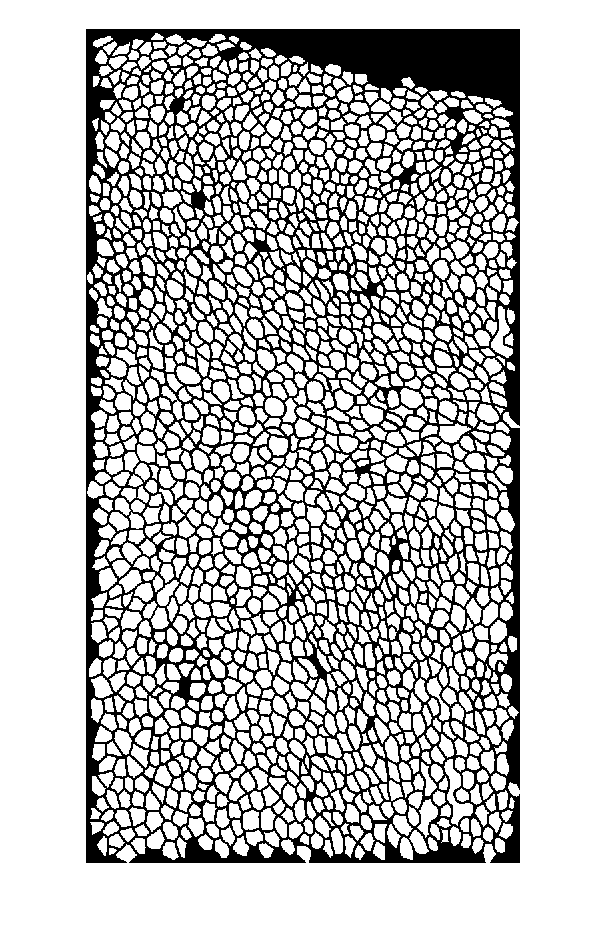

% Downsample all
DSRatio = 0.05;
RGB = imresize(RAWRGB,DSRatio);
CellMask = imresize(RAWBoundMask,DSRatio);
SupportMask = imresize(RAWSupportMask,DSRatio);

imshow(CellMask)

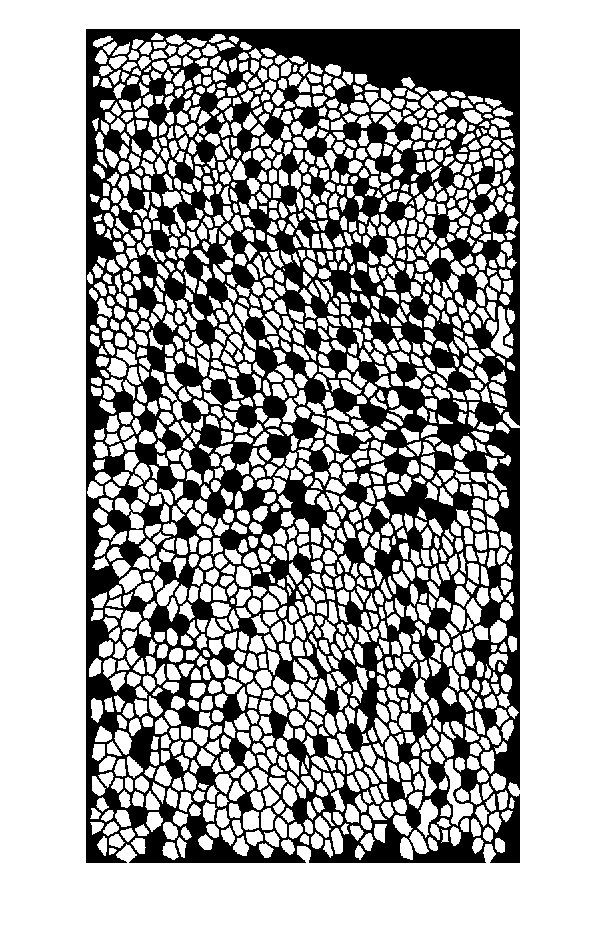

imshow(SupportMask)

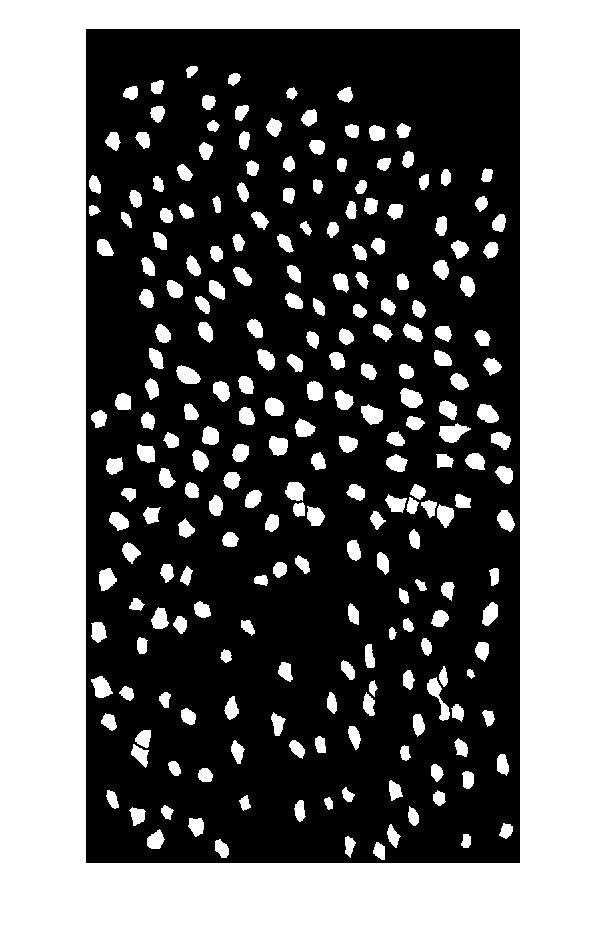

% Generate Mask for Hair Cells.
HairMask = ~(SupportMask+~CellMask);
imshow(HairMask)

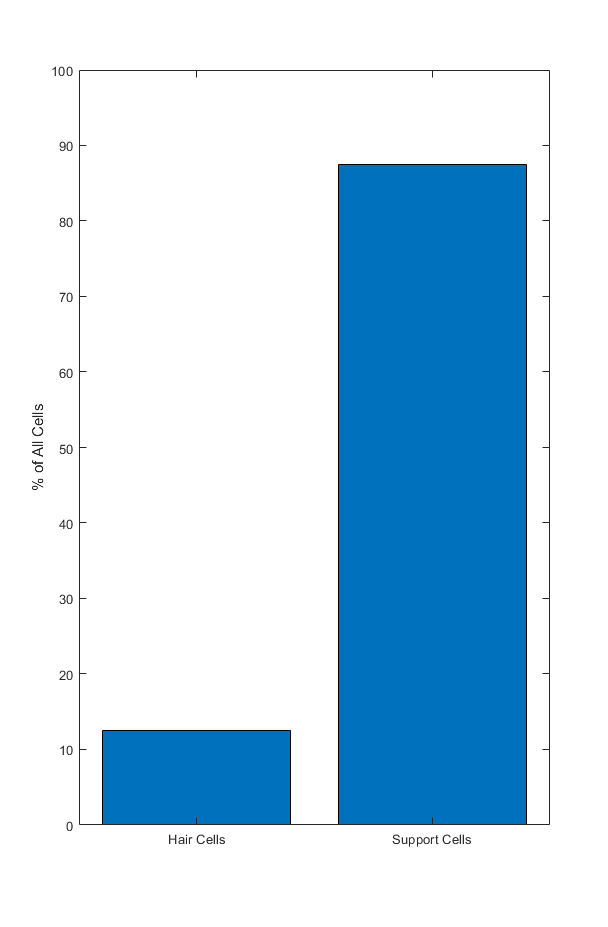

% Generate Labeled Masks
[LCellMask,nCells] = bwlabel(CellMask);
[LSupportMask,nSupportCells] = bwlabel(SupportMask);
[LHairMask,nHairCells] = bwlabel(HairMask);
bar(categorical({'Support Cells','Hair Cells'}),100*[nSupportCells/nCells nHairCells/nCells])
ylabel('% of All Cells')
ylim([0 100])

Hair cells appear to make up about 1/10th of the population of cells in the image. 

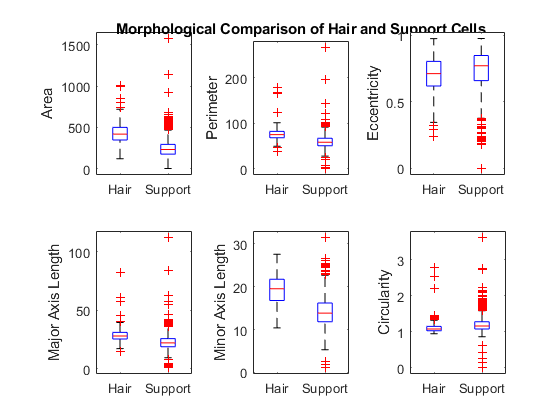

% Morphological comparisons
hairProps = regionprops(HairMask,'Area','Eccentricity','Perimeter','MajorAxisLength','MinorAxisLength');
hairArea = [hairProps.Area]';
hairEcc = [hairProps.Eccentricity]';
hairPer = [hairProps.Perimeter]';
hairMajL = [hairProps.MajorAxisLength]';
hairMinL = [hairProps.MinorAxisLength]';
hairCirc = Circularity(hairArea,hairPer);


supportProps = regionprops(SupportMask,'Area','Eccentricity','Perimeter','MajorAxisLength','MinorAxisLength');
supportArea = [supportProps.Area]';
supportEcc  = [supportProps.Eccentricity]';
supportPer  = [supportProps.Perimeter]';
supportMajL = [supportProps.MajorAxisLength]';
supportMinL = [supportProps.MinorAxisLength]';
supportCirc = Circularity(supportArea,supportPer);

% Combine
cType = [repmat(char('Hair   '),[nHairCells 1]); repmat(char('Support'),[nSupportCells 1])];
cArea = [hairArea; supportArea];
cEccentricity = [hairEcc; supportEcc];
cPerimeter = [hairPer; supportPer];
cMajL = [hairMajL; supportMajL];
cMinL = [hairMinL; supportMinL];
cCirc = [hairCirc; supportCirc];

figure
subplot(2,3,1)
boxplot(cArea,cType)
ylabel('Area')
subplot(2,3,2)
boxplot(cPerimeter,cType)
ylabel('Perimeter')
title('Morphological Comparison of Hair and Support Cells')

subplot(2,3,3)
boxplot(cEccentricity,cType)
ylabel('Eccentricity')
subplot(2,3,4)
boxplot(cMajL,cType)
ylabel('Major Axis Length')

subplot(2,3,5)
boxplot(cMinL,cType)
ylabel('Minor Axis Length')

subplot(2,3,6)
boxplot(cCirc,cType)
ylabel('Circularity')

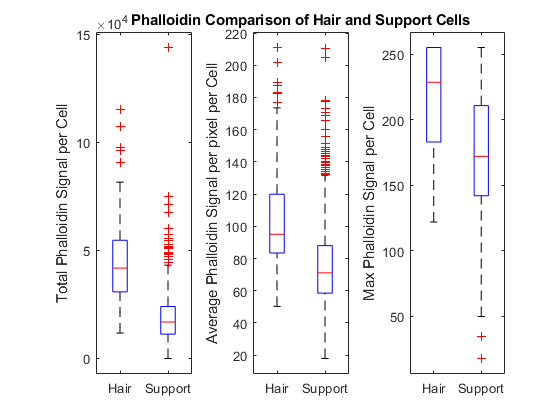

% COMPARISON OF PHALLOIDIN EXPRESSION BETWEEN HAIR and SUPPORT CELLS
% Isolate each cell and group based on type. 
HairCellsRGB = labelSeparate(RGB,LHairMask);
SupportCellsRGB = labelSeparate(RGB,LSupportMask);

% Compute total Phalloidin Signal per cell.
HairCellsPhalloidin = CellFun(HairCellsRGB,'Sum',2);
SupportCellsPhalloidin = CellFun(SupportCellsRGB,'Sum',2);

% HairCellsBW = labelSeparate(HairMask,LHairMask);
% SupportCellsBW = labelSeparate(SupportMask,LSupportMask);
% HairCellsPhalloidin = CellSum(HairCellsRGB,2)./CellSum(HairCellsBW,1);
% SupportCellsPhalloidin = CellSum(SupportCellsRGB,2)./CellSum(SupportCellsBW,1);

cPhalloidin = [HairCellsPhalloidin';SupportCellsPhalloidin'];

% Plot
figure
subplot(1,3,1)
boxplot(cPhalloidin,cType)
ylabel('Total Phalloidin Signal per Cell')
% Compute average Phalloidin Signal per pixel per cell
HairCellsBW = labelSeparate(HairMask,LHairMask);
SupportCellsBW = labelSeparate(SupportMask,LSupportMask);
HairCellsPhalloidin = CellFun(HairCellsRGB,'Sum',2)./CellFun(HairCellsBW,'Sum',1);
SupportCellsPhalloidin = CellFun(SupportCellsRGB,'Sum',2)./CellFun(SupportCellsBW,'Sum',1);

cPhalloidinAve = [HairCellsPhalloidin';SupportCellsPhalloidin'];
% Plot
subplot(1,3,2)
boxplot(cPhalloidinAve,cType)
ylabel('Average Phalloidin Signal per pixel per Cell')
title('Phalloidin Comparison of Hair and Support Cells')
HairCellsPhalloidin = CellFun(HairCellsRGB,'Max',2);
SupportCellsPhalloidin = CellFun(SupportCellsRGB,'Max',2);

cPhalloidinMax = [HairCellsPhalloidin';SupportCellsPhalloidin'];
subplot(1,3,3)
boxplot(cPhalloidinMax,cType)
ylabel('Max Phalloidin Signal per Cell')

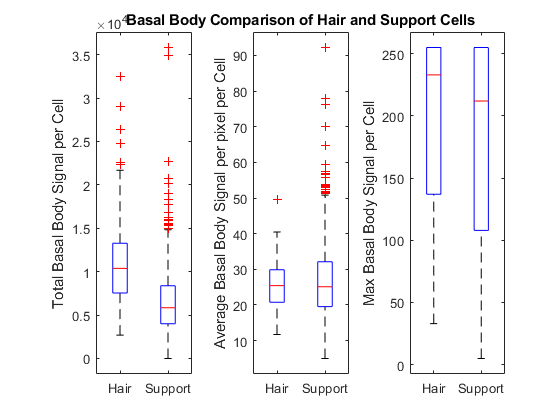

% COMPARISON OF BASAL BODY EXPRESSION BETWEEN HAIR and SUPPORT CELLS
% Isolate each cell and group based on type. 
HairCellsRGB = labelSeparate(RGB,LHairMask);
SupportCellsRGB = labelSeparate(RGB,LSupportMask);

% Compute total Phalloidin Signal per cell.
HairCellsBB = CellFun(HairCellsRGB,'Sum',1);
SupportCellsBB = CellFun(SupportCellsRGB,'Sum',1);

cBB = [HairCellsBB';SupportCellsBB'];

% Plot
figure
subplot(1,3,1)
boxplot(cBB,cType)
ylabel('Total Basal Body Signal per Cell')
% Compute average Basal Body Signal per pixel per cell
HairCellsBW = labelSeparate(HairMask,LHairMask);
SupportCellsBW = labelSeparate(SupportMask,LSupportMask);
HairCellsBB = CellFun(HairCellsRGB,'Sum',1)./CellFun(HairCellsBW,'Sum',1);
SupportCellsBB = CellFun(SupportCellsRGB,'Sum',1)./CellFun(SupportCellsBW,'Sum',1);

cBBave = [HairCellsBB';SupportCellsBB'];
% Plot
subplot(1,3,2)
boxplot(cBBave,cType)
ylabel('Average Basal Body Signal per pixel per Cell')
title('Basal Body Comparison of Hair and Support Cells')
HairCellsBB = CellFun(HairCellsRGB,'Max',1);
SupportCellsBB = CellFun(SupportCellsRGB,'Max',1);

cBBMax = [HairCellsBB';SupportCellsBB'];
subplot(1,3,3)
boxplot(cBBMax,cType)
ylabel('Max Basal Body Signal per Cell')

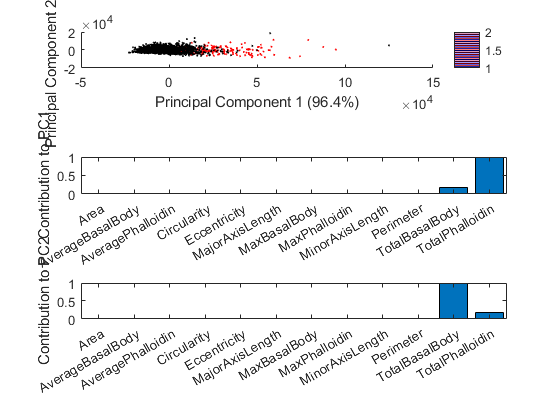

% Principal components Analysis can better identify which of these parameters (or combination of these parameters)
% is best to distinguish between Hair and Support Cells. 

% First combine the different parameters both types into one matrix
cParams = [cArea,cEccentricity,cPerimeter,cMajL,cMinL,cCirc,cPhalloidin,cPhalloidinAve,cPhalloidinMax,cBB,cBBave,cBBMax];
varNames = categorical({'Area','Eccentricity','Perimeter','MajorAxisLength','MinorAxisLength','Circularity','TotalPhalloidin','AveragePhalloidin','MaxPhalloidin','TotalBasalBody','AverageBasalBody','MaxBasalBody'});
[coeff,score,~,~,explained,mu] = pca(cParams);

% vColor = char([repmat(char('r'),[nHairCells 1]); repmat(char('b'),[nSupportCells 1])]);
vColor =[ones([nHairCells 1]); repmat(2,[nSupportCells 1])];
figure
subplot(3,1,1)
scatter(score(:,1),score(:,2),1,vColor)
colormap('flag')
xlabel(sprintf('Principal Component 1 (%2.1f%%)',explained(1)))
ylabel(sprintf('Principal Component 2 (%2.1f%%)',explained(2)))
subplot(3,1,2)
bar(varNames,abs(coeff(:,1)));
ylabel('Contribution to PC1');
subplot(3,1,3)
bar(varNames,abs(coeff(:,2)));
ylabel('Contribution to PC2');

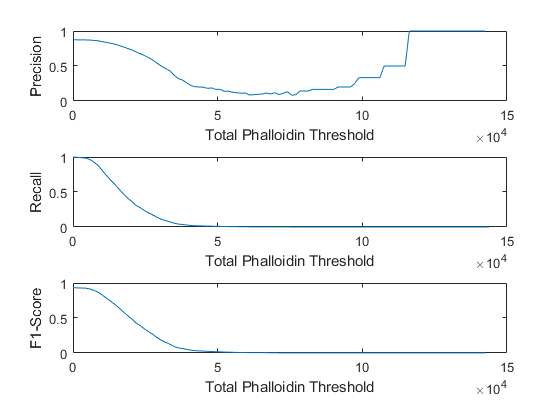

nThresh = 100;
Threshes = linspace(min(cPhalloidin),max(cPhalloidin),nThresh);

kType = vColor-1; % Known Type
kMat = double(repmat(kType,[1 nThresh]));

pMat = double(repmat(cPhalloidin,[1 nThresh])>Threshes); % Predicted type for each threshold. 

Positives = sum(pMat);
Negatives = sum(~pMat);

TruePositives = sum(kMat.*pMat);
TrueNegatives = sum((kMat+pMat)==0);

FalsePositives = Positives-TruePositives;
FalseNegatives = Negatives-TrueNegatives;

Precision = TruePositives./(TruePositives+FalsePositives);
Recall = TruePositives./(TruePositives+FalseNegatives);

F1Score = 2*(Precision.*Recall)./(Precision+Recall);

figure
subplot(3,1,1)
plot(Threshes,Precision)
xlabel('Total Phalloidin Threshold')
ylabel('Precision')

subplot(3,1,2)
plot(Threshes,Recall)
xlabel('Total Phalloidin Threshold')
ylabel('Recall')

subplot(3,1,3)
plot(Threshes,F1Score)
xlabel('Total Phalloidin Threshold')
ylabel('F1-Score')

% thresh = quantile(HairCellsPhalloidin,0.05);
% thresh = 3*10^4;
% pType = cPhalloidin>thresh;
% TP = sum(kType.*pType);
% TN = sum((kType+pType)==0);
% Pos = sum(pType);
% Neg = sum(~pType);
% FP = Pos-TP;
% FN = Neg-TN;


function [stat] = CellFun(CellIn,Func,dim)
    nEl = length(CellIn);
    stat = zeros(1,nEl);
    for k=1:nEl
        if strcmp(Func,'Sum')
            stat(k) = sum(sum(CellIn{k}(:,:,dim)));
        elseif strcmp(Func,'Max')
            stat(k) = max(max(CellIn{k}(:,:,dim)));
        end
    end
end

function [out] = Circularity(Area,Perimeter)
    out = (Perimeter.^2)./(4*pi*Area);
end
